**Numerical Methods Midterm Exam 2022 - Solutions**

a. Find and display all **real roots** of the following polynomial to 8 decimal places accuracy.


$$\(p\left(x\right)=2x-5x^2-x^3-2x^7\)$$


% Enter solution here
rr = Q1_1()

real roots : 
2.80530310
-0.15265155
-0.15265155


rr = 1×3 cell array
    {["2.80530310"]}    {["-0.15265155"]}    {["-0.15265155"]}


b. Plot the polynomial over an appropriate domain and mark on the real roots with large red circles.

% Enter solution here
Q1_2(rr)

    {["2.80530310"]}    {["-0.15265155"]}    {["-0.15265155"]}



c. Find the locations of any local extrema of $p(x)$ and plot them with large green diamonds.

% Enter solution here
second_diff = Q1_3()

local maxima: 
   0.189197122768149



$$second\_diff = -84\,x^{5}-6\,x-10$$

d. Find the locations of any points of inflections and plot them with large purple stars.

% Enter solution here
Q1_4(second_diff)

   1.0e-71 *

  0.000000000000000 + 0.452783953941336i  0.000000000000000 - 0.452783953941336i  0.000000000000000 + 0.452783953941336i  0.000000000000000 - 0.452783953941336i



2.  The speed v of a Saturn V rocket in vertical flight near the surface of earth can be approximated by:

where,

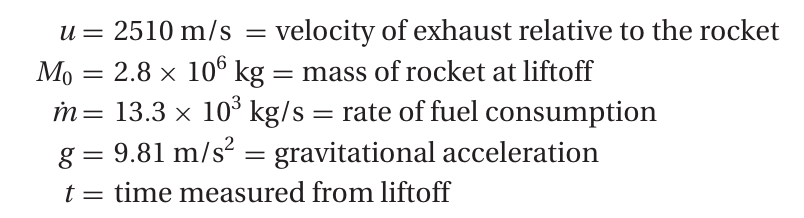

Determine the time when the rocket reaches the speed of sound (335 m/s).

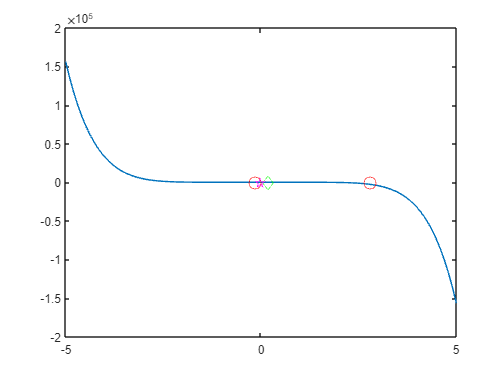

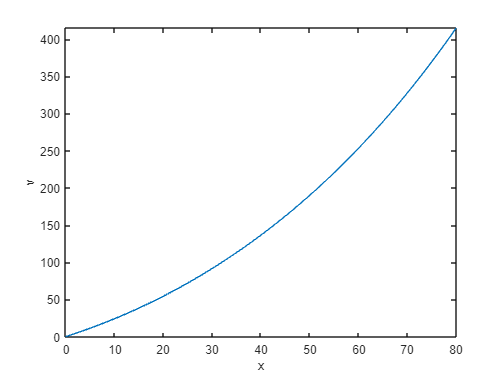

  70.877972268081066



% Enter solution here
Q2()

3. Find all real solutions to the following system of equations on the domain $-\pi/2 \leq x\leq \pi/2, \,\,\,\, -5 \leq x\leq 5$ to 7 decimal places then create a plot which displays the solution.


$$\tan(2x - 1)=1 + \cos(y) \\
\cos(x)=2\sin^2(y)$$


% Enter solution here

4. Three tensile tests were carried out on an aluminium bar. In each test the strain was measured at the same values of stress.

The results were:

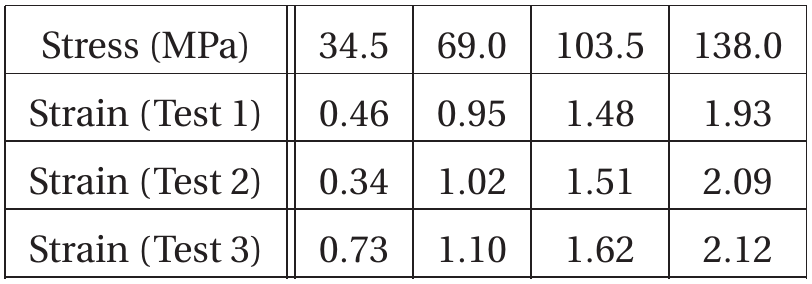

where the units of strain are mm/m ("millimetres per metre"). 

Plot the data then use linear regression to estimate the modulus of elasticity of the bar (modulus of elasticity = stress/strain). Plot the regression line on the same figure as the data.

% Enter solution here


5. The following data is to be fit to a power equation of the form,

$w = Ax^By^Cz^D$,

where A, B, C and D are constants. 

Use linearisation and regression to estimate the values of A. B. C and D then use the fitted power equation to estimate the value of w at the point $(x,y,z) = (3.5, 2.3, 7.1)$.

Data:


$$\matrix{
x & y & z & w \cr
4 & 6 & 8 & 34.68 \cr
1 & 6 & 12 & 9.47 \cr
2 & 10 & 12 & 25.61 \cr
1 & 10 & 6 & 5.97 \cr
1 & 4 & 6 & 4.46 \cr
5 & 7 & 10 & 58.22 \cr
4 & 6 & 15 & 61.07 \cr
2 & 9 & 8 & 17.19 \cr
5 & 9 & 11 & 68.75 \cr
1 & 10 & 7 & 6.86 \cr
}$$


% Enter solution here


6. Consider the following multivariable function:


$$\(f\left(x,y\right)=\frac{10-y}{x-3}\)$$


We wish to evaluate $\(f\left(\frac{1,000,000}{333,333},\frac{5}{7}\right)\)$ in Matlab.

a. What is the true relative error when rounding the $x$ and $y$ values to 6 decimal places in the calculation?

% Enter solution here
f = Q6_1()

relative_error =      9.691716093137368e-07


True Solution: 3095235.000212
Rounded Solution: 3095238.000026
Relative Error: 0.000001


f = function_handle with value:
    @(x,y)(10-y)/(x-3)


b. What is the true absolute error when using double precision in the calculation?

% Enter solution here
Q6_2(f)

True Solution: 3095235.000212
Double Solution: 3095235.000212
Absolute Error: 0.00000000


c. To calculate the relative error in part (a) you had to divide a relatively small number by a relatively large number. Can you trust that value or not? Explain/demonstrate why the relative error you calculated can either be trusted or not.

% Enter solution here
% the value can't be trusted because due to floating pint limitation, the
% actual true solution is unable to be acheived, the is the decimal points
% error in the output.

Q6_3()

 --- FUNCTIONS ---

A space to place your functions so that after running the code blocks below you can then use them in the scripts above.

function rr = Q1_1()
    %real roots = r(imag(r) == 0) filters the roots to include only those with zero imaginary part
    coefficient = [2, -5, -1, -2];
    r = roots(coefficient);
    rr = {};

    disp("real roots : ")
    for n = 1 : length(r)
        rr{end + 1} = sprintf("%.8f", real(r(n)));
        fprintf("%.8f\n", real(r(n)))
    end
    return
end


function Q1_2(rr)
    disp(rr)
    p = @(x) 2 * x - 5 * (x.^2) - x.^3 -2 * (x.^7);
    x = linspace(-5, 5, 100);
    plot(x, p(x))
    hold on
    % Plot the real roots with large red circles
    for n = 1 : length(rr)
        root = str2double(rr{n}); % Convert string to double
        plot(root, 0, 'ro', 'MarkerSize', 10);
    end
end


function second_diff = Q1_3()
    syms x
    p = @(x) 2 * x - 5 * (x.^2) - x.^3 -2 * (x.^7);
    local_minima = [];
    local_maxima = [];

    % Find critical points by solving p'(x) = 0
    critPts = solve(diff(p(x), x) == 0, x);

    for n = 1 : length(critPts)
        % take second diff to find if it's maxima or minima
        second_diff = diff(diff(p(x), x), x);
        x_crit = critPts(n);
        
        % substitute x critical points into second div
        if double(subs(second_diff, x, x_crit)) > 0
            local_minima(end + 1) = x_crit;
        elseif double(subs(second_diff, x, x_crit)) < 0
            local_maxima(end + 1) = x_crit;
        end
    end
    disp("local maxima: ")
    disp(local_maxima)
    
    if length(local_maxima) >= 1
        for n = 1 : length(local_maxima)
            plot(local_maxima(n), p(local_maxima(n)), 'gd', 'MarkerSize', 8)
        end
    end
    return
end


function Q1_4(second_diff)
    % point of inflection is where the graph changes it concave, slope down
    % to up or slope up to down
    
    syms x
    p = @(x) 2 * x - 5 * (x.^2) - x.^3 -2 * (x.^7);

    %Find the critical point where the derivative changes signs
    secCritPts = solve(second_diff == 0, x);

    inflectionPts = [];

    for n = 1:length(secCritPts)
        concavity = double(subs(second_diff, x, secCritPts(n)));
        if concavity ~= 0
            inflectionPts(end + 1) = concavity;
        end
    end
    disp(inflectionPts)
    for n = 1:length(inflectionPts)
        plot(inflectionPts(n), p(inflectionPts(n)), 'mp', 'MarkerSize', 8)
    end
end


function Q2()
    %log_10_x = log10(x); % Common logarithm (base 10)
    %log_2_x = log(x, 2); % Logarithm to base 2
    
    %syms t
    hold off
    v = @(t) (2510) * log((2.8 * (10^6) / (2.8 * (10^6) - (13.3 * (10^3)) * t))) - 9.81 * t;
    
    % Define an anonymous function that calculates the difference between v(t) and 335
    equation = @(t) v(t) - 335;
    fplot(v, [0, 80])        % fplot used to plot function
    xlabel('x')
    ylabel('v')
    
    % Use fzero to find the root of the difference function
    initial_guess = 60; % Provide an initial guess for the root
    t_roots = fzero(equation, initial_guess);
    disp(t_roots);
end


function f = Q6_1()
    % Relative error = absolute error / measured value
    % absolute error = correct value - measured value
    f = @(x, y) (10 - y)/(x - 3);

    x = 1000000/333333;
    y = 5/7;

    roundX = round(x, 6);
    roundY = round(y, 6);

    realSol = f(x,y);
    roundSol = f(roundX,roundY);

    relative_error = abs(realSol - roundSol) / abs(realSol);
    relative_error
    
    fprintf('True Solution: %.6f\n', realSol);
    fprintf('Rounded Solution: %.6f\n', roundSol);
    fprintf('Relative Error: %f\n', relative_error);

    return
end

function Q6_2(f)
    x = 1000000/333333;
    y = 5/7;

    realSol = f(x,y);

    doubleX = double(x);
    doubleY = double(y);

    doubleSol = f(doubleX, doubleY);
    absolute_error = abs(realSol - doubleSol);

    fprintf('True Solution: %.6f\n', realSol);
    fprintf('Double Solution: %.6f\n', doubleSol);
    fprintf('Absolute Error: %.8f\n', absolute_error);
end

function Q6_3()
    f = @(x, y) (10 - y)/(x - 3);
    x = 3.1;
    y = 5/7;

    demonSol = f(x, y);
end
